**Giordano Dylan - Martelet Curtis                            L3 EEA_Gr TP1**

# Rapport TP1: Analyse Spectrale Optique

clc
close all


## I. Partie Théorique

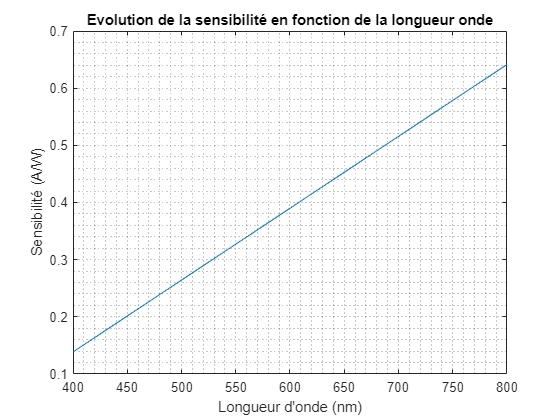

lambda=linspace(400,800,41);
a=(0.58-0.14)/(750-400);
b=0.39-a*600;
y=a.*lambda+b;

figure()
plot(lambda,y);
title("Evolution de la sensibilité en fonction de la longueur onde")
xlabel("Longueur d'onde (nm)"); ylabel("Sensibilité (A/W)")
grid minor

## II. Partie Expérimentale

### 1) Etude d'une source de lumière blanche

**1/**    Je relève un photocourant de 6.13µA pour la lumière blanche.

**2/**    A la sortie du miroir M3, la lumière est maintenant uniquement rouge.

Je relève un photocourant de 472nA.

**3/**

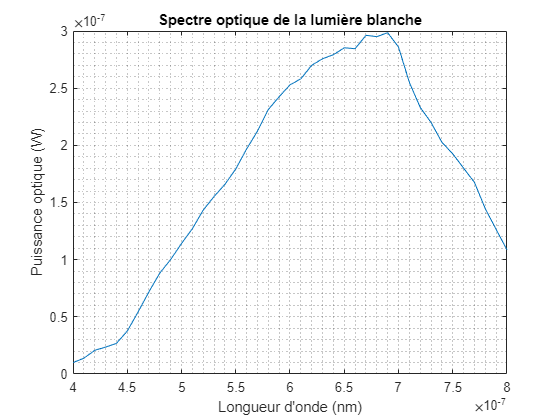

lum_blanc = load("donnée1TP1.txt");

figure()
plot(lum_blanc(:,3),-lum_blanc(:,4))
title("Spectre optique de la lumière blanche")
xlabel("Longueur d'onde (nm)")
ylabel("Puissance optique (W)")
grid minor

**4/µ**

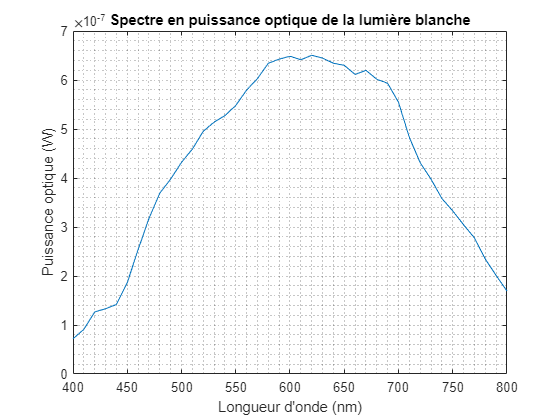

Puissance = -lum_blanc(:,4)./y';

figure()
plot(lambda,Puissance)
xlabel("Longueur d'onde (nm)")
ylabel("Puissance optique (W)")
title("Spectre en puissance optique de la lumière blanche")
grid minor

**5/**    On peut en conclure que la lumière blanche est composée de toutes les longueurs d'ondes du visible (de 400 à 800nm), mais principalement d'ondes aux alentours de 600nm.

**6/**

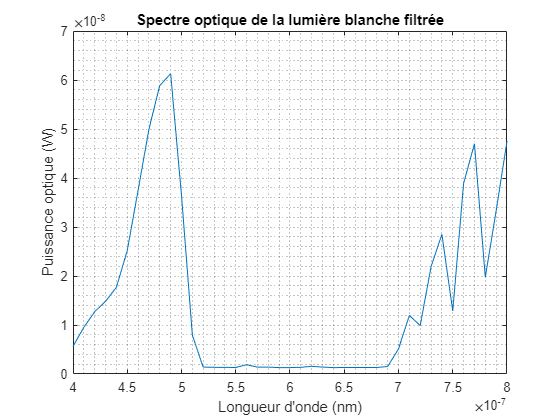

laser = load("mes2TP1.txt");

figure()
plot(laser(:,3),-laser(:,4))
title("Spectre optique de la lumière blanche filtrée")
xlabel("Longueur d'onde (nm)")
ylabel("Puissance optique (W)")
grid minor

**7/**    On peut observer que de 520nm à 690nm, la puissance optique est quasi nulle. Le spectre de transmission de ce filtre est donc compris entre [0;520[ U ]700;800] nm.

**8/**

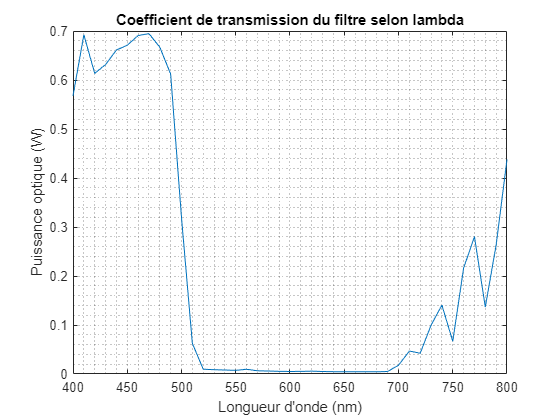

Transmission_Filtre = laser(:,4)./lum_blanc(:,4);

figure()
plot(lambda,Transmission_Filtre)
title("Coefficient de transmission du filtre selon lambda")
xlabel("Longueur d'onde (nm)"); ylabel("Puissance optique (W)")
grid minor

**9/**    En électronique, on peut apparenter ce filtre a un coupe bande.

## 2) Etude d'un Laser Hélium-Néon

**1/**    En fermant la fente, on observe que la tache lumineuse s"étale sur l"axe horizontal: on a une diffraction. 

La fonction mathématique est un sinus cardinal.

**2/**    Je relève un photocourant de 350nA.

**3/**    On observe sur le graphe un pic à environ 640nm. 

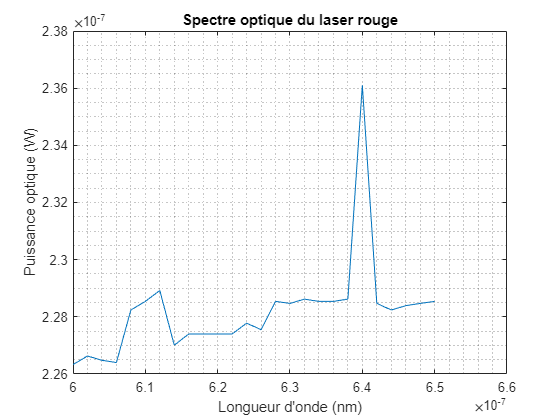

laser = load("data3.txt");

figure()
plot(laser(:,3),-laser(:,4))
title("Spectre optique du laser rouge")
xlabel("Longueur d'onde (nm)")
ylabel("Puissance optique (W)")
grid minor

**4/**    Nous n'avons pas besoin de traiter ce spectre avec la courbe de sensibilité de la photodiode car le laser emet une seule longueur d'onde: il est monochromatique. On a donc pas besoin de corriger.